# EXERCISE #1 : Build a simplistic WLAN Scenario Simulation

## Part 1 : AP generates beacon frames only

- Beacon is set to run at 10x TU

- Simulation time = (100x TU)

- Explore objects used in Network Simulator

- Explore measurements

Copyright 2024-2025 The MathWorks, Inc.

#### Cleanup

clear;
format shortEng;
% Set seed of random number generator for reproducible results
rng(1,"combRecursive");

### General settings

- `5 GHz band`

- `20 MHz wide channel`

- `Channel 36`

- [https://www.mathworks.com/help/releases/R2024b/wlan/gs/wlan-radio-frequency-channels.html](https://www.mathworks.com/help/releases/R2024b/wlan/gs/wlan-radio-frequency-channels.html)

band        = 5;
bandwidth   = 20e6;
channel     = 36;

% Use wlanChannelFrequency() function to get the actual RF center frequency for channel 36
% Hint: Type "doc wlanChannelFrequency" in the MATLAB Command Window, and see the "Syntax" section.
fc          = wlanChannelFrequency(channel,band)

fc =      5.1800e+009


txPower     = 0.0; % dBm - Use 0 dBm to make calculations easy...
txGain      = 0.0; % dB  - Will use this field to mimic additional attenuation

- `Time Unit = 1024us`

TU              = 1024e-6;
simulationTime  = 100*TU;

### Geometry

- Define position of AP and STA

AP_pos  = [-10,-10,0];
STA_pos = [10,10,0];

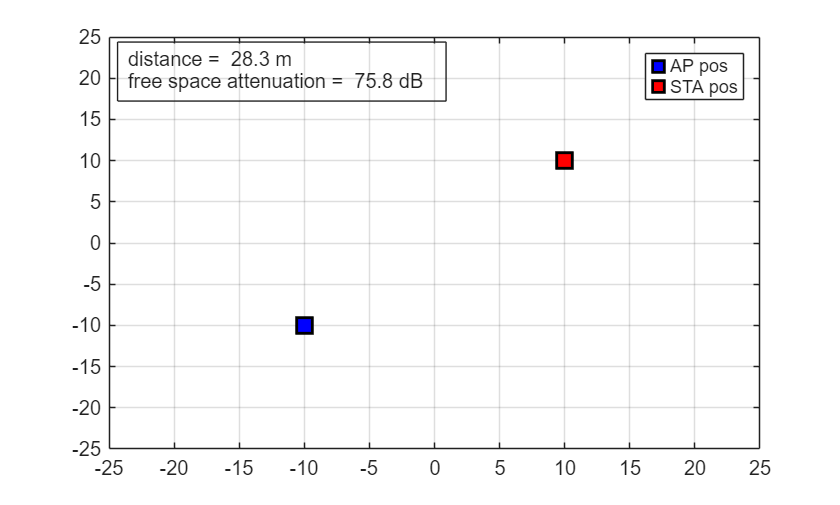

[dist, atten] = plotStations(AP_pos,STA_pos,fc);

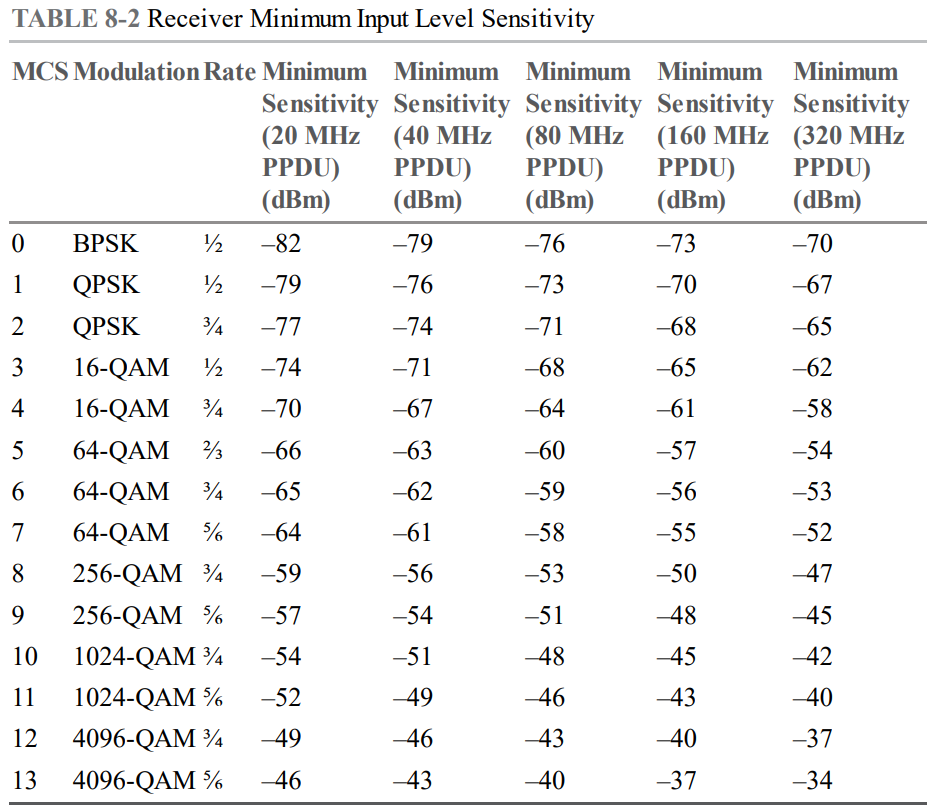

#### Create a wirelessNetworkSimulator instance

networkSimulator = wirelessNetworkSimulator.init;

### Create AP

- 802.11n type

- Send a beacon each TU (1024us)

- AP is located at [0, 0, 0]

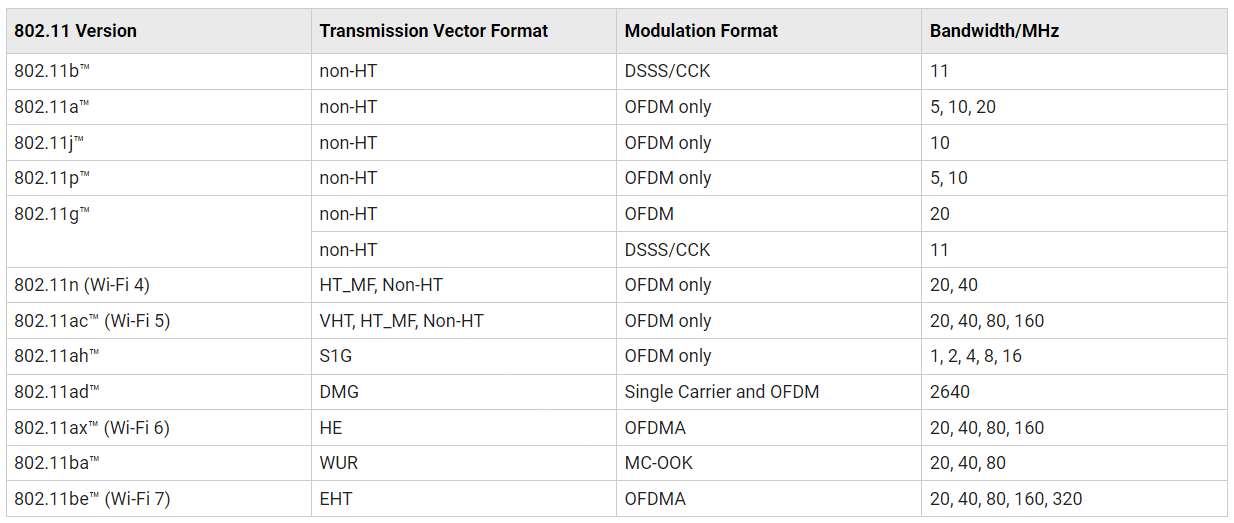

%doc wlanDeviceConfig

- [https://www.mathworks.com/help/releases/R2024b/wlan/gs/802-11-standards-supported-by-wlan-toolbox-for-phy-modeling.html](https://www.mathworks.com/help/releases/R2024b/wlan/gs/802-11-standards-supported-by-wlan-toolbox-for-phy-modeling.html)

APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat", "HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",txPower, ...    
    "TransmitGain",txGain, ...
    "MCS",6, ...
    "AggregateHTMPDU",false, ...
    "BeaconInterval", 10 ...
    );

totalAttenuation = atten - APCfg.TransmitGain

totalAttenuation =     75.7593e+000


%doc wlanNode

AP = wlanNode(...
    "Name","AP",...
    "Position",AP_pos, ...
    "DeviceConfig",APCfg,...    
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

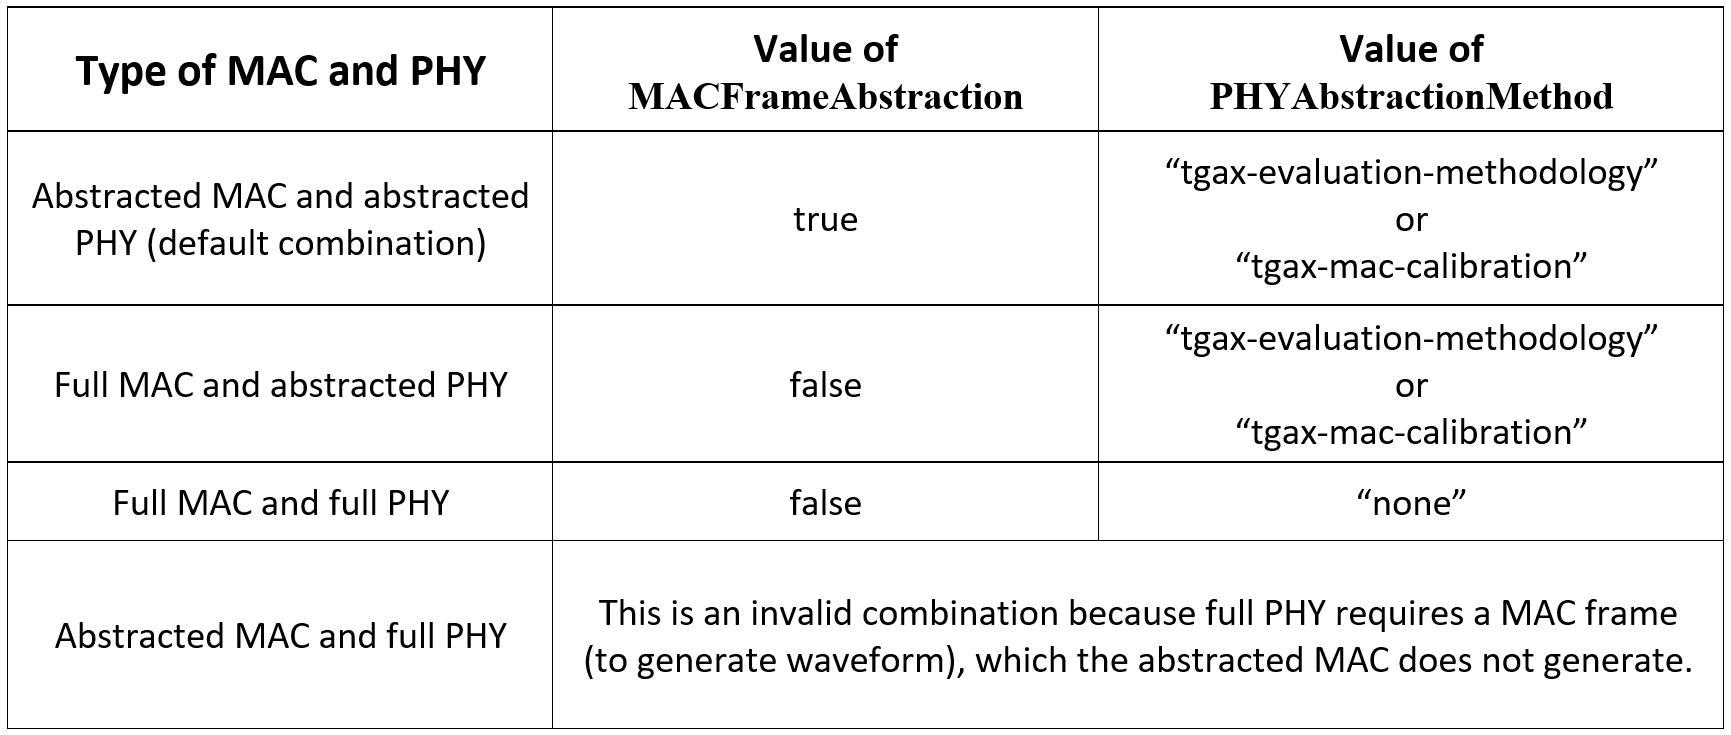

### Create STA

- 802.11n type

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",0, ...    
    "MCS",3);

STA = wlanNode(...
    "Name","STA",...
    "Position",STA_pos, ...
    "DeviceConfig",STACfg,...    
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Associate AP with STA

### Define traffic type

- Beacon Only (default)

- Bidirectional

- DL

- UL

trafficType = "DL"

trafficType = "DL"

associateStations(AP,STA,"FullBufferTraffic",trafficType);

Is full buffer using one in particular ? – Full buffer configuration always generates traffic of AC0, as of now. So, the generated traffic is filled in AC0 queues.

Is it specified in the 802.11 standard ? – No, traffic generation part is not specified in the standard.

Can it be used while QoS traffic has been defined ? – As full buffer configuration generates AC0 traffic, you can still install traffic of other ACs (AC1, AC2, AC3) using ‘addTrafficSource’. For AC0 traffic, you can either use full buffer configuration or install traffic of AC0 using ‘addTrafficSource’.

Was it the only way of sending information before EDCA and QoS were introduced ? – Traffic generation is implementation dependent and not part of EDCA and QoS. EDCA and QoS define how the generated traffic is differentiated, prioritized, and queued. Full buffer just represents a traffic pattern where a node always has data to send at any point of time. This pattern can be applied for any AC, but we support it for only AC0 in our simulation.

#### Run the simulation

- WirelessNetworkSimulator is an event-driven simulator

- use the run() method to start the simulation

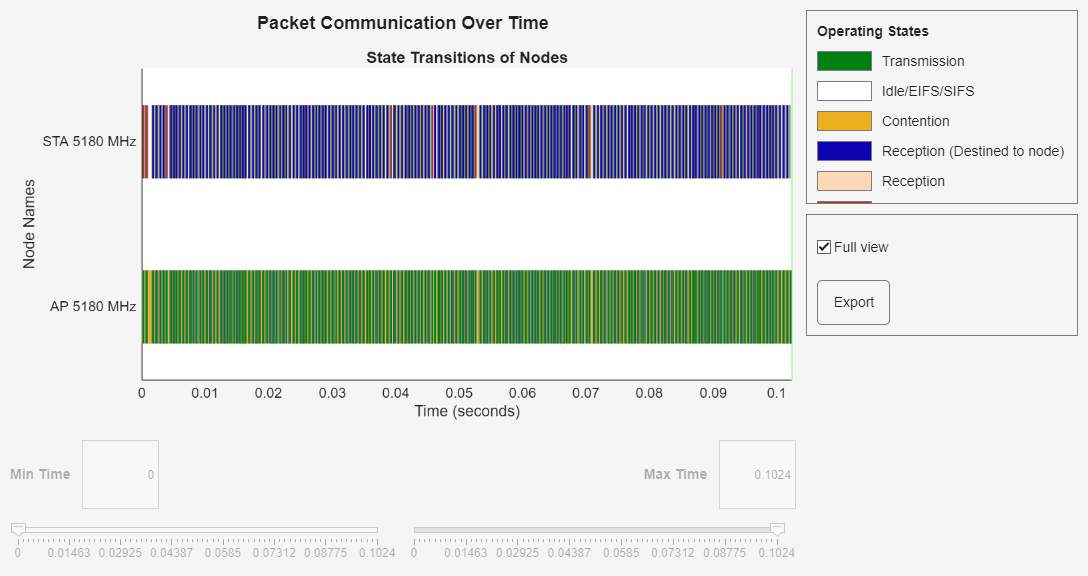

addNodes(networkSimulator,{AP, STA})
enablePacketVisualization = true;
% Enable packet visualization 
if enablePacketVisualization
    packetVisObj = hPlotPacketTransitions({AP, STA},simulationTime,FrequencyPlotFlag=false);
end
run (networkSimulator,simulationTime)

## Visualize statistics at AP

% Create a variable names APStatistics 
% Hint:  Type web('https://www.mathworks.com/help/releases/R2024b/wlan/ref/wlannode.statistics.html') in the MATLAB Command Window and see the "Syntax" section.
APStatistics = statistics(AP,"all")

APStatistics = struct with fields:
    Name: "AP"
      ID: 1.0000e+000
     App: [1×1 struct]
     MAC: [1×1 struct]
     PHY: [1×1 struct]
    Mesh: [1×1 struct]


### APP Layer statistics

APStatistics.App

ans = struct with fields:
    TransmittedPackets: 431.0000e+000
      TransmittedBytes: 646.5000e+003
       ReceivedPackets: 0.0000e+000
         ReceivedBytes: 0.0000e+000
          Destinations: [1×1 struct]


- `Explore the list of statistics the networkSimulator object maintains`

- `We have not defined any traffic so far, only TransmittedBeaconFrames should be populated`

### MAC Layer Statistics

APStatistics.MAC

ans = struct with fields:
            TransmittedDataFrames: 184.0000e+000
          TransmittedPayloadBytes: 262.5000e+003
      SuccessfulDataTransmissions: 175.0000e+000
          RetransmittedDataFrames: 8.0000e+000
                TransmittedAMPDUs: 0.0000e+000
             TransmittedRTSFrames: 184.0000e+000
           TransmittedMURTSFrames: 0.0000e+000
             TransmittedCTSFrames: 0.0000e+000
           TransmittedMUBARFrames: 0.0000e+000
             TransmittedAckFrames: 0.0000e+000
        TransmittedBlockAckFrames: 0.0000e+000
           TransmittedCFEndFrames: 0.0000e+000
    TransmittedBasicTriggerFrames: 0.0000e+000
          TransmittedBeaconFrames: 10.0000e+000
               ReceivedDataFrames: 0.0000e+000
             ReceivedPayloadBytes: 0.0000e+000
                   ReceivedAMPDUs: 0.0000e+000
                ReceivedRTSFrames: 0.0000e+000
              ReceivedMURTSFrames: 0.0000e+000
                ReceivedCTSFrames: 184.0000e+000
              ReceivedM

- `Ability to extract a specific element :`

APStatistics.MAC.TransmittedBeaconFrames

ans =     10.0000e+000


### `PHY Layer Statistics`

APStatistics.PHY

ans = struct with fields:
         TransmittedPackets: 378.0000e+000
    TransmittedPayloadBytes: 287.4200e+003
            ReceivedPackets: 359.0000e+000
       ReceivedPayloadBytes: 5.0260e+003
             DroppedPackets: 0.0000e+000


### Explore statisctics at the STA

STAStatistics = statistics(STA);
STAStatistics.PHY

ans = struct with fields:
         TransmittedPackets: 359.0000e+000
    TransmittedPayloadBytes: 5.0260e+003
            ReceivedPackets: 377.0000e+000
       ReceivedPayloadBytes: 285.8900e+003
             DroppedPackets: 0.0000e+000


STAStatistics.MAC

ans = struct with fields:
            TransmittedDataFrames: 0.0000e+000
          TransmittedPayloadBytes: 0.0000e+000
      SuccessfulDataTransmissions: 0.0000e+000
          RetransmittedDataFrames: 0.0000e+000
                TransmittedAMPDUs: 0.0000e+000
             TransmittedRTSFrames: 0.0000e+000
           TransmittedMURTSFrames: 0.0000e+000
             TransmittedCTSFrames: 184.0000e+000
           TransmittedMUBARFrames: 0.0000e+000
             TransmittedAckFrames: 175.0000e+000
        TransmittedBlockAckFrames: 0.0000e+000
           TransmittedCFEndFrames: 0.0000e+000
    TransmittedBasicTriggerFrames: 0.0000e+000
          TransmittedBeaconFrames: 0.0000e+000
               ReceivedDataFrames: 175.0000e+000
             ReceivedPayloadBytes: 262.5000e+003
                   ReceivedAMPDUs: 0.0000e+000
                ReceivedRTSFrames: 184.0000e+000
              ReceivedMURTSFrames: 0.0000e+000
                ReceivedCTSFrames: 0.0000e+000
              ReceivedMU


STAStatistics.MAC.ReceivedBeaconFrames

ans =     10.0000e+000


STAStatistics.App

ans = struct with fields:
    TransmittedPackets: 0.0000e+000
      TransmittedBytes: 0.0000e+000
       ReceivedPackets: 174.0000e+000
         ReceivedBytes: 261.0000e+003


### Further Exploration

- [https://www.mathworks.com/help/releases/R2024b/wlan/ug/getting-started-with-wlan-system-level-simulation-in-matlab.html](https://www.mathworks.com/help/releases/R2024b/wlan/ug/getting-started-with-wlan-system-level-simulation-in-matlab.html)